**Mimic Brownian motion / Noise through high frequency harmonic oscilaltions & Power spectrum**


% Parameters for the simulation
num_oscillators = 10000;  % number of oscillators
t_end = 1000; % simulation end time
dt = 0.01; % time step size
t = 0:dt:t_end; % time vector

% Parameters for the oscillators
frequencies = randn(num_oscillators, 1); % frequencies of the oscillators
amplitudes = randn(num_oscillators, 1); % amplitudes of the oscillators
phases = 2*pi*rand(num_oscillators, 1); % phases of the oscillators

% Initialize the position vector
x = zeros(size(t));

% Calculate the position for each time point using all the oscillators
for i = 1:length(t)
    x(i) = sum(amplitudes .* cos(2*pi*frequencies*t(i) + phases));
end

Arrays have incompatible sizes for this operation.

Related documentation


figure
plot(t, x)
title('"Rauschen" mittels überlagerten harmonischen Oszillatoren')
xlabel('Zeit')
ylabel('Amplitude')

% Calculate the Fourier Transform of the signal
X = fft(x);

% Calculate the power spectrum (magnitude squared of each frequency component)
Pxx = abs(X).^2 / length(t);

% Frequency vector (considering only half the spectrum due to symmetry)
f = (0:(length(t)/2-1)) / (t_end); 

% Plot the power spectrum
figure
plot(f, Pxx(1:length(f)))
title('FFT des harmonischen "Rausch-Signals"')
xlabel('Frequenz')
ylabel('Amplitude')



**Noise & Power Spectrum**

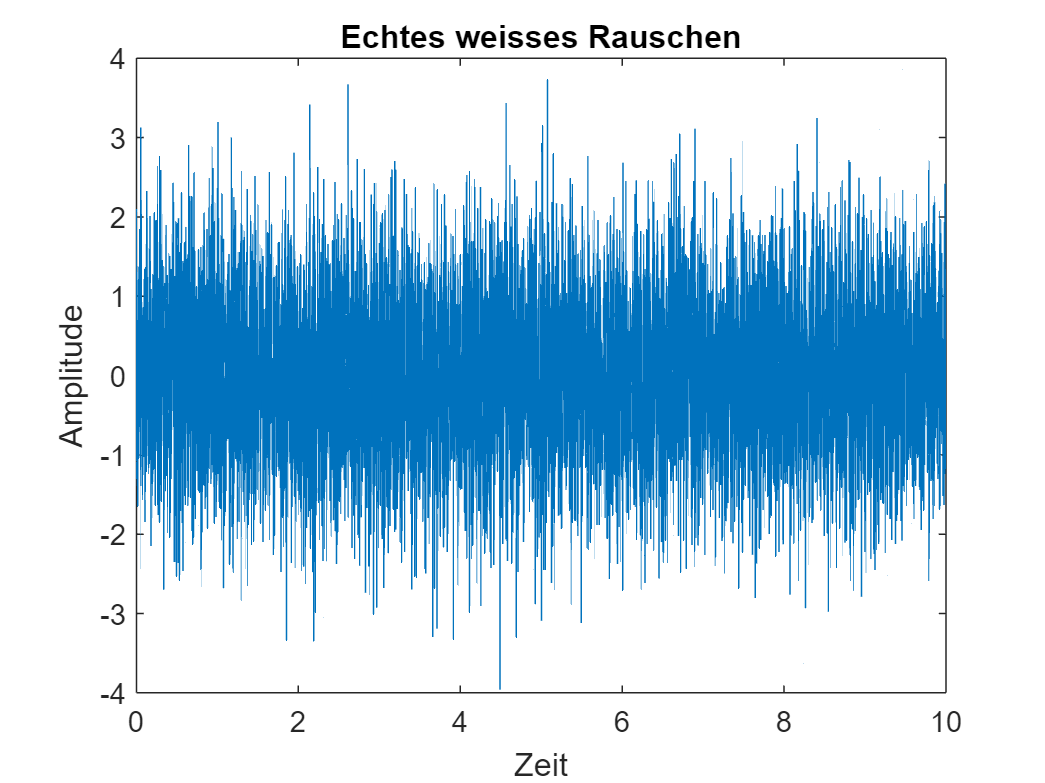

% Parameters
N = 10000;  % Number of samples
fs = 1000;  % Sampling rate in Hz
T = N/fs;   % Total time
t = (0:N-1)/fs;  % Time vector

% Generate white noise
noise = randn(1, N);

% Plot the noise signal
figure(1);
plot(t, noise);
xlabel('Zeit');
ylabel('Amplitude');
title('Echtes weisses Rauschen');

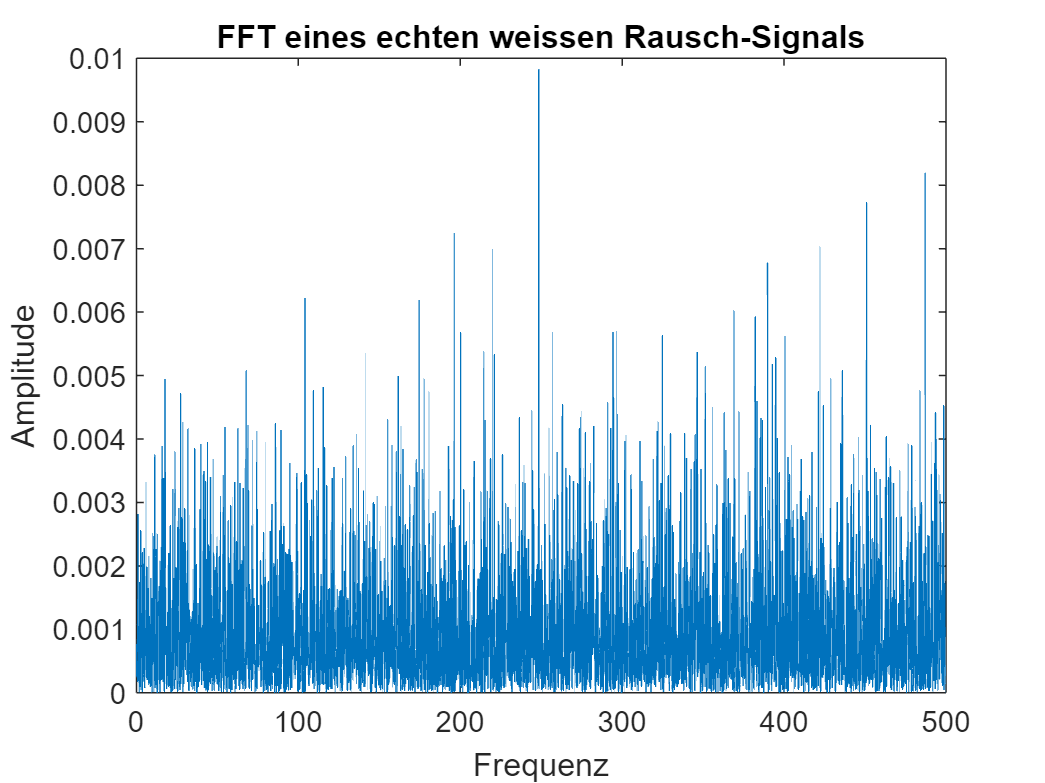

%title('White Noise (N=10000, f=1000)');

% Compute the Fourier transform
f_noise = fft(noise);

% Compute the power spectrum
Pxx = (1/(fs*N)) * abs(f_noise).^2;

% Frequency vector
f = 0:fs/N:fs/2;

% Plot the power spectrum
figure(2);
plot(f, Pxx(1:length(f)));
xlabel('Frequenz');
ylabel('Amplitude');
title('FFT eines echten weissen Rausch-Signals');


% Show that power spectral density is approximately constant
mean_Pxx = mean(Pxx(1:length(f)));
disp(['Mean power spectral density: ', num2str(mean_Pxx)]);

Mean power spectral density: 0.00099343
